% declare constants
DIM = 3;
SAMPLES = 10000;
SIMULATE = 1000;
% set seed 
rng(4864)

% Test that the Q function is working correctly
test_Q = simulate_Q(eye(DIM), SAMPLES);

res = zeros(1, size(test_Q, 3));
for i=1:size(test_Q, 3)
    res(1, i) = orthogonal(test_Q(:,:,i));
end

% if this equals 1 then the funciton is working
all(res)

ans = logical
   1


% get the approximate integral of the trace function
[expected, allT] = expected_trace(test_Q);
expected

expected = 0.0170

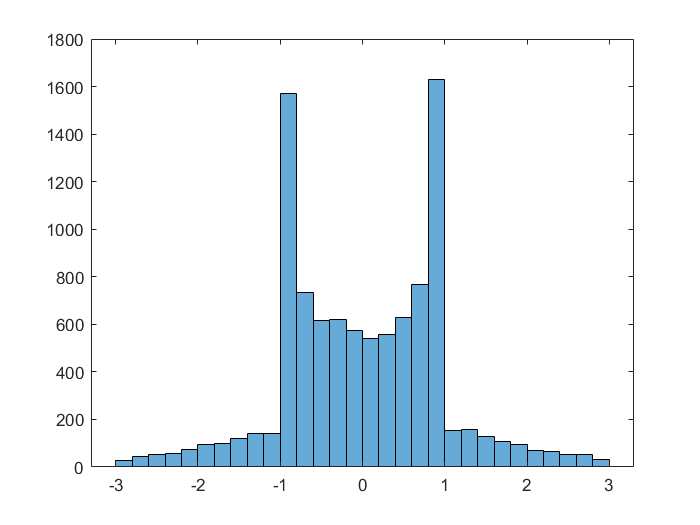

histogram(allT)

% simular the markov chain many times
sim1 = simulate_traces(SIMULATE, DIM, SAMPLES);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


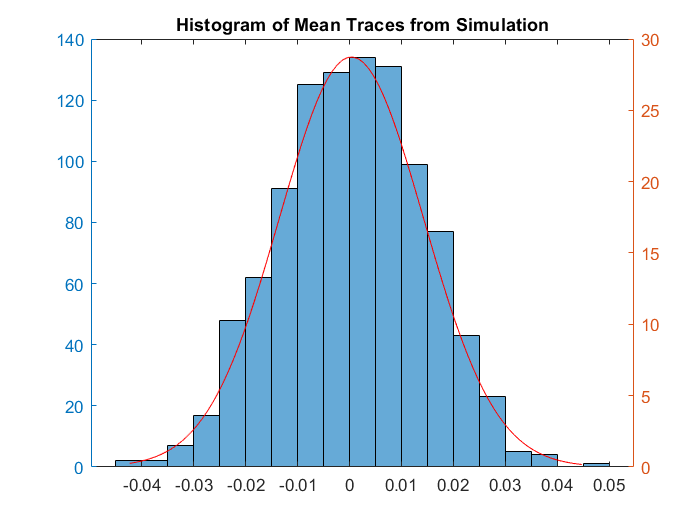

% plot the histogram of the expected trace from each simulation
clf;
title("Histogram of Mean Traces from Simulation")
yyaxis left
histogram(sim1)
hold on 
yyaxis right
x = min(sim1):0.001:max(sim1);
% overlay normal distribution
y = normpdf(x, mean(sim1), sqrt(var(sim1)));
plot(x, y, 'r')

mean(sim1)

ans = 3.6918e-04

var(sim1)

ans = 1.9268e-04

prctile(sim1, [2.5, 97.5])

ans =    -0.0256    0.0267


% normal approximation bootstrap
alpha = 0.05;
[mean(sim1) - norminv(1 - alpha / 2) * std(sim1), mean(sim1) + norminv(1 - alpha / 2) * std(sim1)]

ans =    -0.0268    0.0276


% bootstrap the trace from a single markov chain
original_estimate = mean(allT);
boot_data = stat_star(allT, @mean, 10000);
boot_CI = [original_estimate - prctile(boot_data - original_estimate, 97.5), ...
    original_estimate - prctile(boot_data - original_estimate, 2.5)];
boot_CI

boot_CI =    -0.0023    0.0361


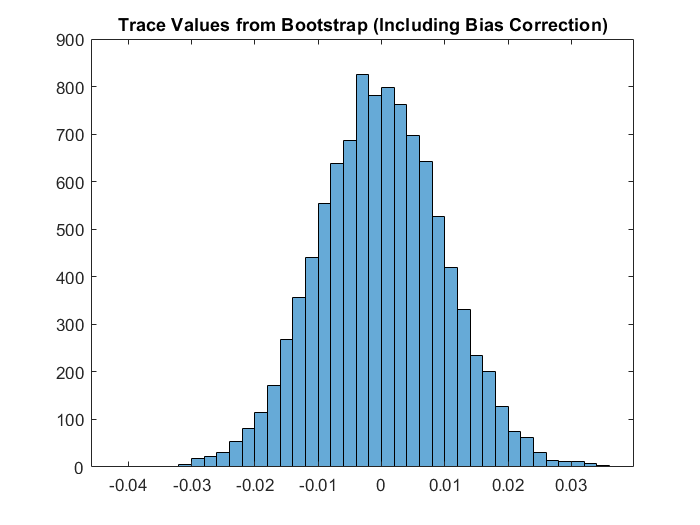

% plot the bootstrapped traces
clf;
histogram(boot_data - original_estimate);
hold on;
title("Trace Values from Bootstrap (Including Bias Correction)");

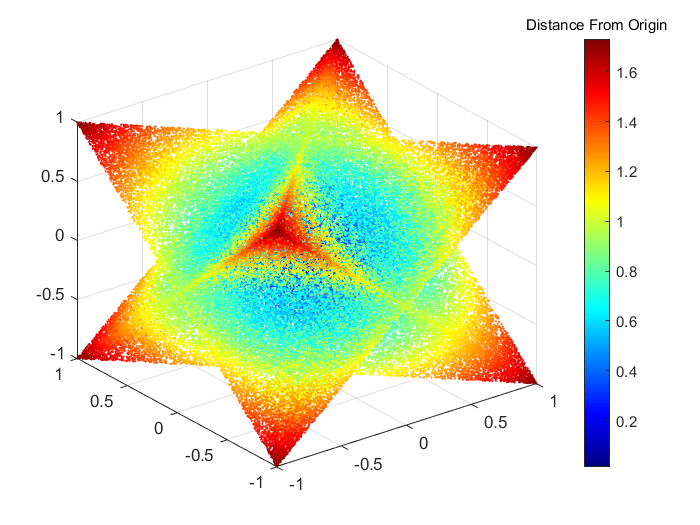

% visualizing the different indexes of the data
clf;
scatter3(squeeze(test_Q(1,1,:)), squeeze(test_Q(2,2,:)), squeeze(test_Q(3,3,:)), ...
    1, sqrt(squeeze(test_Q(1,1,:)).^2 +squeeze(test_Q(2,2,:)).^2 + squeeze(test_Q(3,3,:)).^2));
colormap(jet);
cb = colorbar();
title(cb, "Distance From Origin")

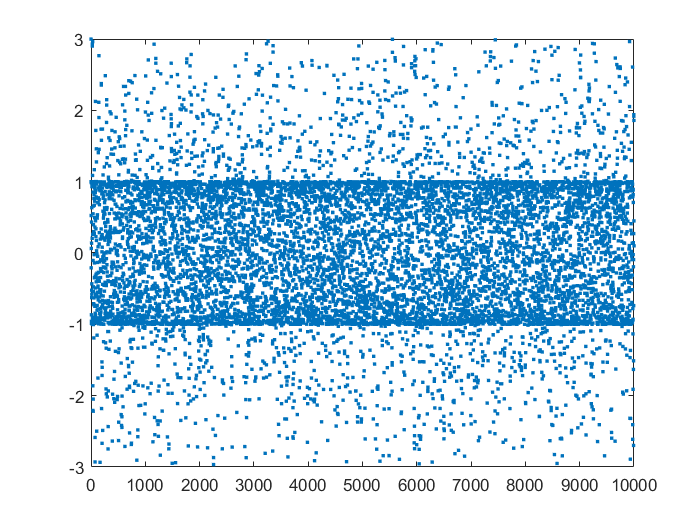

% plot time series of traces
plot(allT, '.')

This is for the second method

https://jarrodmcclean.com/integrating-over-the-unitary-group/


% Test that the Q function is working correctly
test_Q2 = random_unitary(DIM, SAMPLES);

res2 = zeros(1, size(test_Q2, 3));
for i=1:size(test_Q2, 3)
    res2(1, i) = orthogonal(test_Q2(:,:,i));
end

% if this equals 1 then the funciton is working
all(res2)

ans = logical
   1


% get the approximate integral of the trace function
[expected2, allT2] = expected_trace(test_Q2);
expected2

expected2 = 0.0045

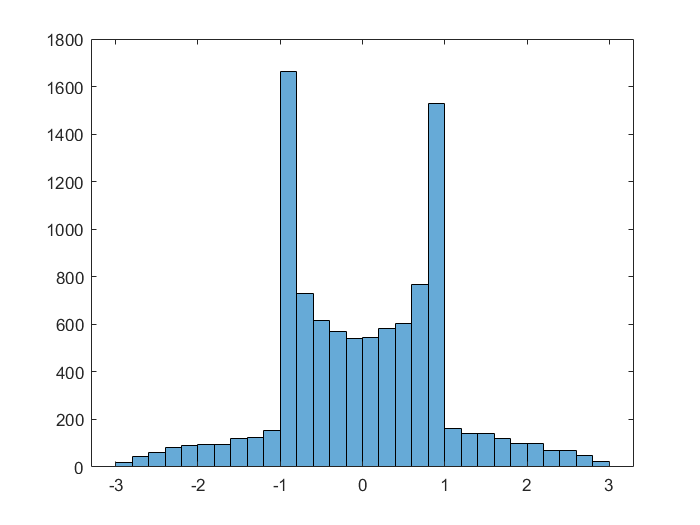

histogram(allT2)

% simular the markov chain many times
sim2 = simulate_traces_method2(SIMULATE, DIM, SAMPLES);

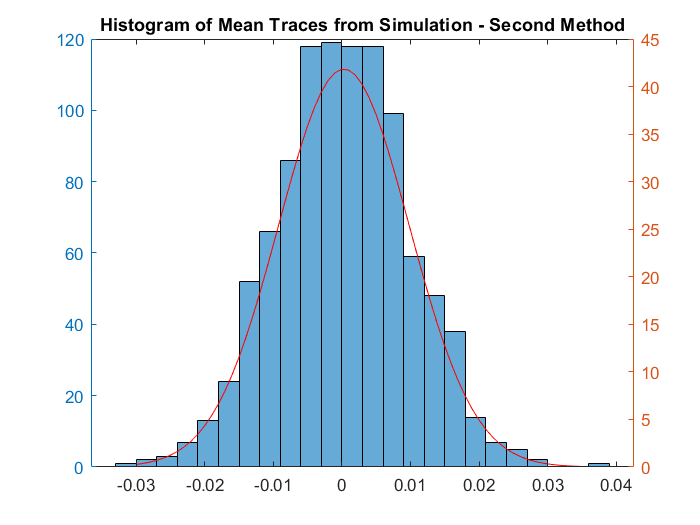

% plot the histogram of the expected trace from each simulation
clf;
title("Histogram of Mean Traces from Simulation - Second Method")
yyaxis left
histogram(sim2)
hold on 
yyaxis right
x = min(sim2):0.001:max(sim2);
% overlay normal distribution
y = normpdf(x, mean(sim2), sqrt(var(sim2)));
plot(x, y, 'r')

mean(sim2)

ans = 2.8421e-04

var(sim2)

ans = 9.0909e-05

prctile(sim2, [2.5, 97.5])

ans =    -0.0182    0.0189


% normal approximation bootstrap
alpha = 0.05;
[mean(sim2) - norminv(1 - alpha / 2) * std(sim2), mean(sim2) + norminv(1 - alpha / 2) * std(sim2)]

ans =    -0.0184    0.0190


% bootstrap the trace from a single markov chain
original_estimate2 = mean(allT2);
boot_data2 = stat_star(allT2, @mean, 10000);
boot_CI2 = [original_estimate2 - prctile(boot_data2 - original_estimate2, 97.5), ...
    original_estimate2 - prctile(boot_data2 - original_estimate2, 2.5)];
boot_CI2

boot_CI2 =    -0.0150    0.0234


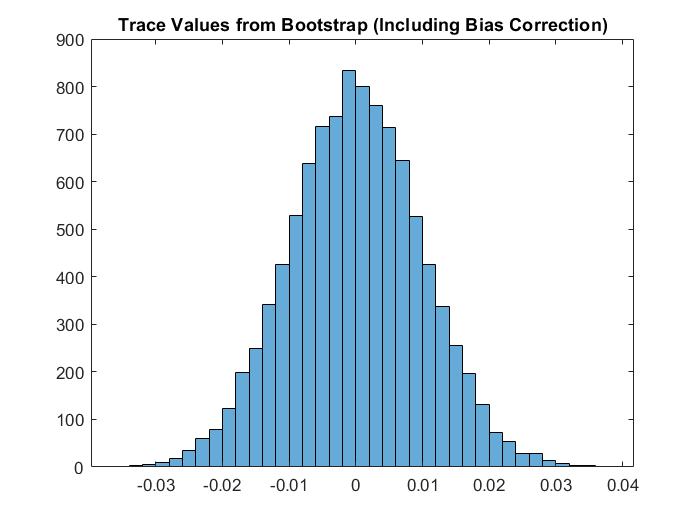

% plot the bootstrapped traces
clf;
histogram(boot_data2 - original_estimate2);
hold on;
title("Trace Values from Bootstrap (Including Bias Correction)");

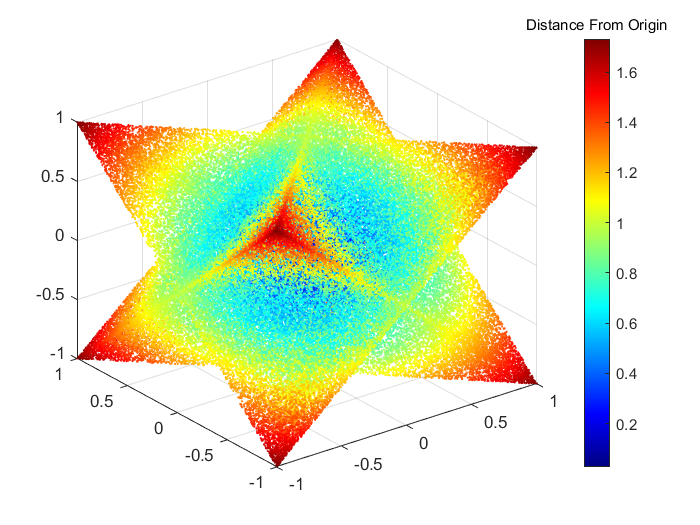

% visualizing the different indexes of the data
clf;
scatter3(squeeze(test_Q2(1,1,:)), squeeze(test_Q2(2,2,:)), squeeze(test_Q2(3,3,:)), ...
    1, sqrt(squeeze(test_Q2(1,1,:)).^2 +squeeze(test_Q2(2,2,:)).^2 + squeeze(test_Q2(3,3,:)).^2));
colormap(jet);
cb = colorbar();
title(cb, "Distance From Origin")

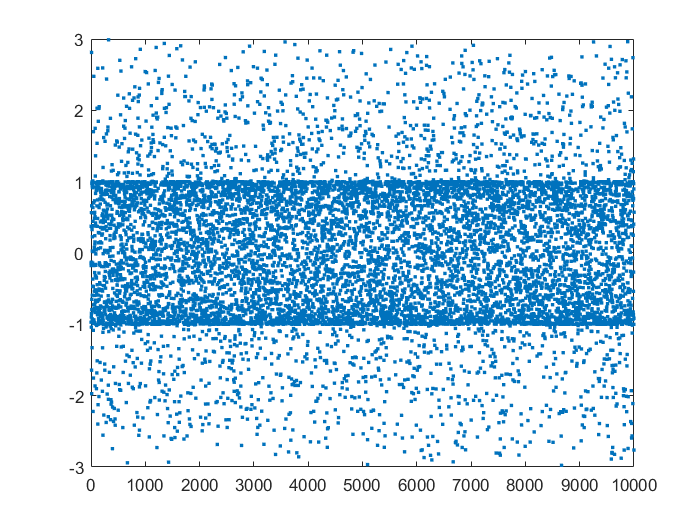

plot(allT2, '.')